% This file is used for task 10. 


% This copies the initial table loaded in Q9 to a new variable called
% AllData.  
AllData = DeepLearningTable_start;



% Convert teh labels to categories
AllData.Ratings = categorical(AllData.Ratings);

% Variables are named to end in Q10 for readiability and to ensure that the
% Correct variables are used in their correct spots. 



% Splitting the data into the training and validating portions. 
cvp = cvpartition(AllData.Ratings,'Holdout',0.2);
TrainingDataQ10 = AllData(training(cvp),:);
RemainingDataQ10 = AllData(test(cvp),:);

cvp = cvpartition(RemainingDataQ10.Ratings,'Holdout',0.5);
ValidationDataQ10 = RemainingDataQ10(training(cvp),:);
TestingDataQ10 = RemainingDataQ10(test(cvp),:);

% Getting the text and the labels assocaited with them for the training,
% validation, and testing sets. 
TrainingTextDataQ10 = TrainingDataQ10.Reviews;
ValidationTextDataQ10 = ValidationDataQ10.Reviews;

YTrainQ10 = TrainingDataQ10.Ratings;
YValidationQ10 = ValidationDataQ10.Ratings;

TestingReviewsQ10 = TestingDataQ10.Reviews;
TestingLablesQ10 = TestingDataQ10.Ratings;



% Preprocessing the text data with my self defined function. Remember the
% bags are used to ensure my preprocess text function will run the way i
% want it too. It is not used so it does not matter the values associated
% with it
tokenziedDocsQ10 = tokenizedDocument(TrainingTextDataQ10);
randombag = bagOfWords();
TrainingDocumentsQ10 = preprocessText(TrainingTextDataQ10,randombag);

terms_2 = 17196

number_of_terms_removed_by2 = -17196

terms_3 = 17007

number_of_terms_removed_by3 = 189

terms_4 = 16622

number_of_terms_removed_by_4 = 385

terms_5 = 11954

number_of_terms_removed_by5 = 4668

terms_6 = 11635

number_of_terms_removed_by6 = 319

terms_7 = 11328

number_of_terms_removed_by7 = 307

terms_8 = 11217

number_of_terms_removed_by8 = 111

ValidationDocumentsQ10 = preprocessText(ValidationTextDataQ10,randombag);

terms_2 = 5824

number_of_terms_removed_by2 = -5824

terms_3 = 5752

number_of_terms_removed_by3 = 72

terms_4 = 5451

number_of_terms_removed_by_4 = 301

terms_5 = 3956

number_of_terms_removed_by5 = 1495

terms_6 = 3896

number_of_terms_removed_by6 = 60

terms_7 = 3770

number_of_terms_removed_by7 = 126

terms_8 = 3756

number_of_terms_removed_by8 = 14


%pre-process the test set and remember to use the random bag
TestingDocumentsQ10 = preprocessText(TestingReviewsQ10,randombag);

terms_2 = 5932

number_of_terms_removed_by2 = -5932

terms_3 = 5849

number_of_terms_removed_by3 = 83

terms_4 = 5553

number_of_terms_removed_by_4 = 296

terms_5 = 4087

number_of_terms_removed_by5 = 1466

terms_6 = 4007

number_of_terms_removed_by6 = 80

terms_7 = 3870

number_of_terms_removed_by7 = 137

terms_8 = 3857

number_of_terms_removed_by8 = 13

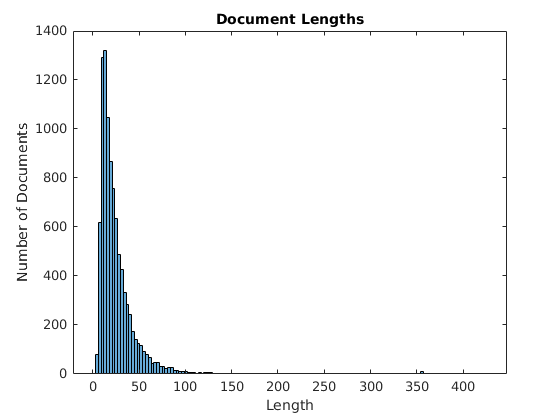





% Creating a word Encoding to ensure that we can retrain the model.
% And convert the documents to sequances. 
enc = wordEncoding(TrainingDocumentsQ10);

% Pad and truncate the documents
documentLengths = doclength(TrainingDocumentsQ10);
figure
histogram(documentLengths)
title("Document Lengths")
xlabel("Length")
ylabel("Number of Documents")


% Convert the documents to sequences and save them to the training and
% testing values. 
sequenceLength = 100;
TrainXQ10 = doc2sequence(enc,TrainingDocumentsQ10,'Length',sequenceLength);
ValidationXQ10 = doc2sequence(enc,ValidationDocumentsQ10,'Length',sequenceLength); 
TestXQ10 = doc2sequence(enc,TestingDocumentsQ10,'Length',sequenceLength);

% This recreates the LSTM model from task 9, but it used the encdoing
% created in task 10 instead. This means the numWords is changed to match the new encoding.  
inputSize = 1;
embeddingDimension = 50;
numHiddenUnits = 80;
numWords = enc.NumWords;
numClasses = numel(categories(YTrainQ10));
layers = [ ...
    sequenceInputLayer(inputSize)
    wordEmbeddingLayer(embeddingDimension,numWords)
    lstmLayer(numHiddenUnits,'OutputMode','last')
    fullyConnectedLayer(numClasses)
    fullyConnectedLayer(numClasses)
    softmaxLayer
    classificationLayer]

layers =   7x1 Layer array with layers:

     1   ''   Sequence Input          Sequence input with 1 dimensions
     2   ''   Word Embedding Layer    Word embedding layer with 50 dimensions and 11217 unique words
     3   ''   LSTM                    LSTM with 80 hidden units
     4   ''   Fully Connected         5 fully connected layer
     5   ''   Fully Connected         5 fully connected layer
     6   ''   Softmax                 softmax
     7   ''   Classification Output   crossentropyex


% Specify Training Options
%https://www.mathworks.com/help/deeplearning/ref/trainingoptions.html
options = trainingOptions('adam', ...
    'MiniBatchSize',16, ...
    'GradientThreshold',2, ...
    'LearnRateDropFactor',0.2, ...
    'LearnRateDropPeriod',5, ...
    'ValidationData',{ValidationXQ10,YValidationQ10}, ...
    'Plots','training-progress',...
    'Verbose',false)

options =   TrainingOptionsADAM with properties:

           GradientDecayFactor: 0.9000
    SquaredGradientDecayFactor: 0.9990
                       Epsilon: 1.0000e-08
              InitialLearnRate: 1.0000e-03
             LearnRateSchedule: 'none'
           LearnRateDropFactor: 0.2000
           LearnRateDropPeriod: 5
              L2Regularization: 1.0000e-04
       GradientThresholdMethod: 'l2norm'
             GradientThreshold: 2
                     MaxEpochs: 30
                 MiniBatchSize: 16
                       Verbose: 0
              VerboseFrequency: 50
                ValidationData: {{1200×1 cell}  [1200×1 categorical]}
           ValidationFrequency: 50
            ValidationPatience: Inf
                       Shuffle: 'once'
                CheckpointPath: ''
          ExecutionEnvironment: 'auto'
                    WorkerLoad: []
                     OutputFcn: []
        

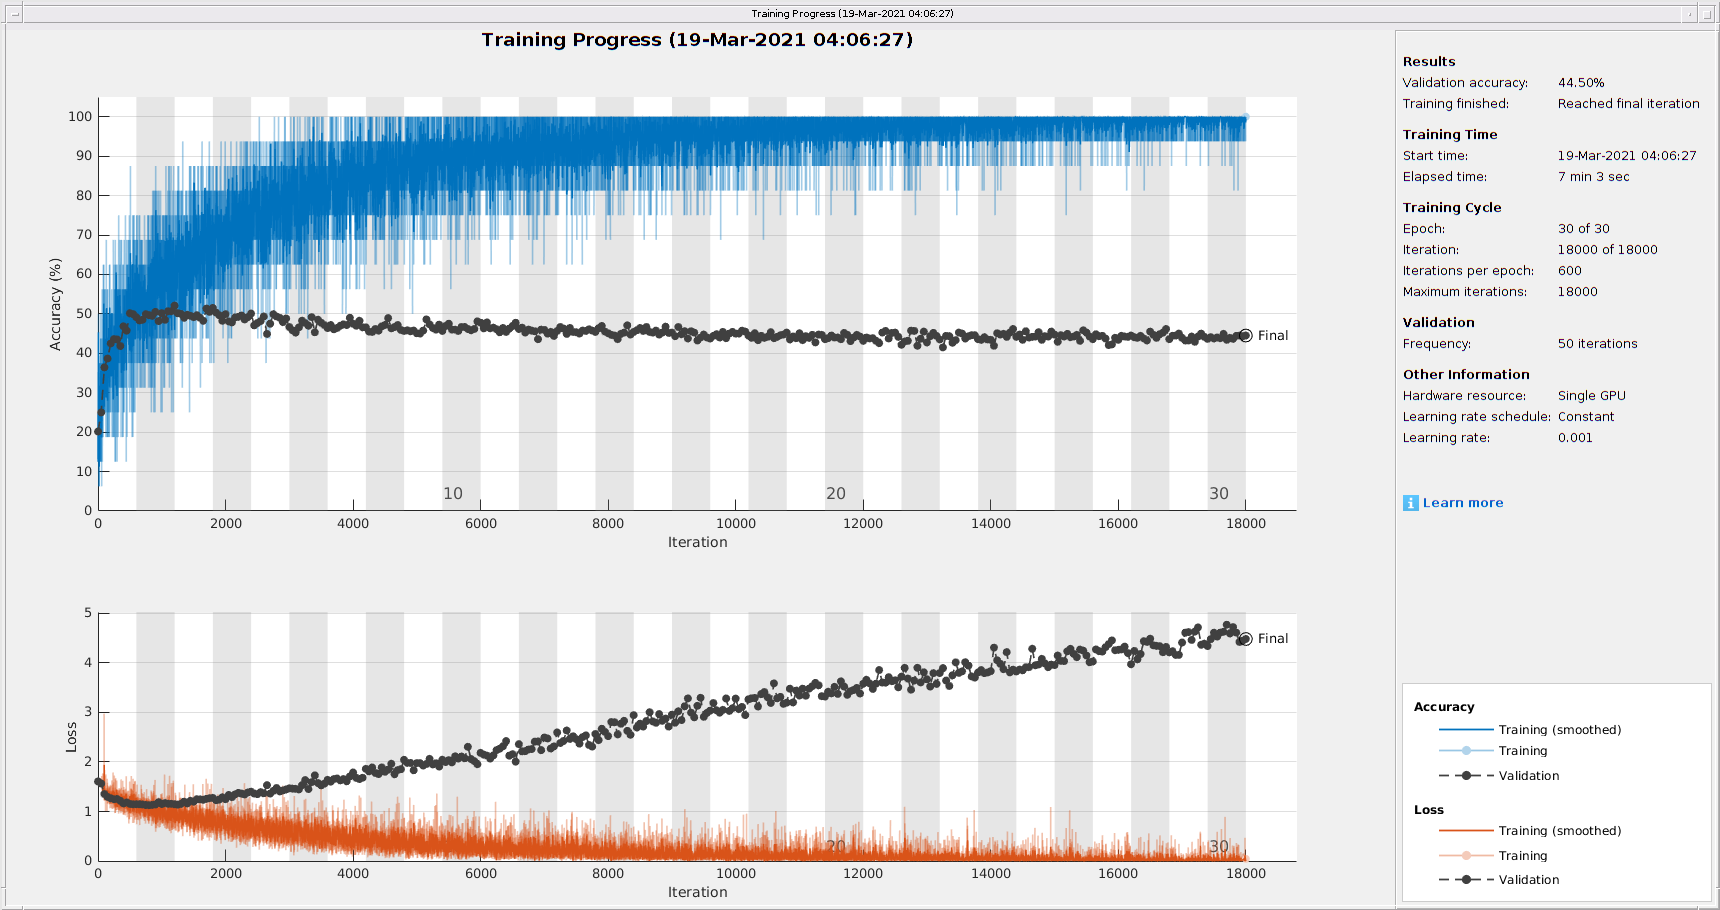



% This re trains the network made in question 9 using the data above. 
net = trainNetwork(TrainXQ10,YTrainQ10,layers,options);


% Predicting using the testing data set defined in the first section. 
PredictResultsTest = classify(net,TestXQ10);
% Checking the results of the test
TestNum = size(TestXQ10,1);
correctNum = 0;
for i=1:TestNum
    % Displaying some results. Will not do it for all
    if i<=20
        sprintf('Review: %s\nPredicted Result: %s\nLabel Rating: %s', TestingReviewsQ10(i),PredictResultsTest(i),TestingLablesQ10(i))
    end
    %Computing the accuracy of the tests
    if PredictResultsTest(i)==TestingLablesQ10(i)
        correctNum = correctNum + 1;
    end
end

ans =     'Review: I ordered a black titanium barbell. Once i recieved it, not even a day later black paint was chipping off my "titanium ring." Obviously the ring wasn't titanium, but painted steel, manipulatinf titanium.
     
     Predicted Result: 2
     Label Rating: 1'


ans =     'Review: Ok so I wanted a ring that could replace my wedding ring till I could get a new one and fell in love with this one till it was sent to me. It looks like a dollar store ring! its cheap looking and I was very disappointed. The one thing that was good about this product is that it was in my mailbox within 2 days of ordering it!
     
     Predicted Result: 2
     Label Rating: 1'


ans =     'Review: I was really disappointed with the product. It is to thin and the chain turns a dark color after a few wears. I have only had this item for 3 weeks and have had to clean it four (4) times already. Would not recommend it for purchase.
     
     Predicted Result: 3
     Label Rating: 1'


ans =     'Review: I just hate this product and ill tell u why. For starters its to flimsy it bends way to easly. After a few days from having it it stareted to get a hair line crack right next to the wolf. I wore it to dinner with my husband and it got snaged on my purse when i was geting something out and it just bent all the way back and snaped off. This pruduct suxs and im glad they arnt selling this awfull thing no more. I would not recomend it to no one. and yes this product does have a beautifull wolf on it but its just not a good sturdy metal.
     
     Predicted Result: 1
     Label Rating: 1'


ans =     'Review: I bought this navel ring awhile ago with clear crystals I thought it was cute and I liked how it is movable. Unfortunately only a couple days after wearing it one jewel fell out, and shortly after that another one fell out too. So I stopped wearing it altogether. I also bought another belly ring from the same company and that one began to tarnish quickly, So I don't think I will be taking any more chances ordering from this company any more.
     
     Predicted Result: 1
     Label Rating: 1'


ans =     'Review: I didn't even have it on for an hour and the chained popped. All I did was get into the car!
     
     Predicted Result: 1
     Label Rating: 1'


ans =     'Review: Very, very, very dissatisfied with this order... NOT the correct size. NOT the item pictured. Not the item titled. Says 18", but it came as 22". I have a small neck... However, it shipped/arrived extremely quickly. ONLY good thing about ordering this item. I could have gotten pretty much the SAME EXACT item for $4.99 from another seller on Amazon. Stole $10 from me.
     
     Predicted Result: 1
     Label Rating: 1'


ans =     'Review: First of all, the one I received was defective. The animated scene sticks once every revolution and stops playing. It is possible to nudge it with a finger and get it going again. By nudging it along, I discovered the box's other flaw. "Silent Night" is horribly abbreviated and doesn't sound remotely right. If you were singing, it would be, "Silent night, holy night. Sleep in heavenly peace."For $20, I didn't expect a symphony. But it isn't even worth $20.Naturally, Amazon has an excellent return policy, so I am satisfied in getting my money back.
     
     Predicted Result: 1
     Label Rating: 1'


ans =     'Review: Well as for the quality of the product it is very good, however it is not what I had purchased and I have had no replies to the messages I have sent.
     
     Predicted Result: 2
     Label Rating: 1'


ans =     'Review: I am returning this necklace. The silver is so bright that it looks fake, and the CZ settings are klunky, not delicate the way it appeared in the photo.
     
     Predicted Result: 2
     Label Rating: 1'


ans =     'Review: I was disappointed that the actual vs. online photo was not attractive. Shipping was very timely and the nice packaging prevented any transit damage. Vendor has a very large selection. The shipping fee assessed at the point of purchase was equal to a fourth of the price of the product at my price point and there is no free shipping on returns. The customer service rep was defensive when I shared my disappointment. A refund was promptly received. I am not interested in reordering.
     
     Predicted Result: 4
     Label Rating: 1'


ans =     'Review: When I recieved these earrings, all the diamonds had been ripped off. Gone. Completely. And to be quite honest, the "ruby" looks like pink plastic stones. Wanted to get them for my mom for christmas, but now I have to send them back and i'm not sure if i'll even get her new present on time before crhistmas.
     
     Predicted Result: 2
     Label Rating: 1'


ans =     'Review: Come on! I thought they had erroneously mailed out CZs! These earrings dont have even the faintest tinge of blue in them! What a RIP! The sterling silver was nice and well-constructed but i purchased these earrings on the strength of what i thought were the dazzling blue topaz stones. Quite a disappointment! I had to buy an emergency back-up Christmas gift for my best friend!
     
     Predicted Result: 5
     Label Rating: 1'


ans =     'Review: I bought a couple of pair of these for my wife for "everyday" ear rings. The tiny stone fell out before she could wear one pair. The earring is so small it makes it difficult to get on. DO NOT BUY THESE.
     
     Predicted Result: 1
     Label Rating: 1'


ans =     'Review: Even if you have the body of a goddess, it's gonna hang funny. Def a bikini piece. No way to really wear it under clothes comfortably
     
     Predicted Result: 1
     Label Rating: 1'


ans =     'Review: even though product was very inexpensive, product showed up at my house broken and falling apart. not a good value at all.
     
     Predicted Result: 2
     Label Rating: 1'


ans =     'Review: Just got my order today and was disappointed. They shipped the box with a bag in it but no charm. How do you mess that order up? How do you stick a bag in a box without the charm inside??
     
     Predicted Result: 1
     Label Rating: 1'


ans =     'Review: Hi ... I had this lady bug charm added to my bracelet ... all of the enamel has chipped off like bad nail polish - thoroughly disappointing, don't waste your money!
     
     Predicted Result: 3
     Label Rating: 1'


ans =     'Review: We ordered these arm bands for my son who wanted pink. He received white. As listing notes that he will receive a mixed assortment, we assumed at least one would be pink. Contacted the seller who insisted that the listing was accurate with what we received. Buyer beware of this seller.
     
     Predicted Result: 1
     Label Rating: 1'


ans =     'Review: My sister purchased this ring for my XX birthday.I absolutely hated it and asked her to return it. She returned the ring and after SEVERAL WEEKS noticed that her credit card hadn't been credited for the return.She contacted this company and they told her that they hadn't received the ring. My sister then proceeded to give the rep. The tracking number that showed that the ring was indeed signed for and received by Palmbeach Jewelry SEVERAL WEEKS ago.She was told to give it another week maybe by then it would be entered into the 'system' as being returned.Sis waited that one week.This time she received a phone call from someone in their accounts department who told her she needed documentation showing that the ring was shipped and received by Palmbeach Jewelry.My sister as well as the USPS faxed over the 'evidence'.You would think that this would be sufficient for this G-d awful company right???NO! Palmbeach Jewelry wanted more information, blood and a right arm!My sis

TestAccuracy = correctNum/TestNum

TestAccuracy = 0.4350


% Creating a confusion matrix to show results 
CTest = confusionmat(TestingLablesQ10,PredictResultsTest)

CTest =    102    46    30    15     7
    59    58    45    29     9
    21    37    64    57    21
    14    19    47   125    95
    10     5    29    83   173


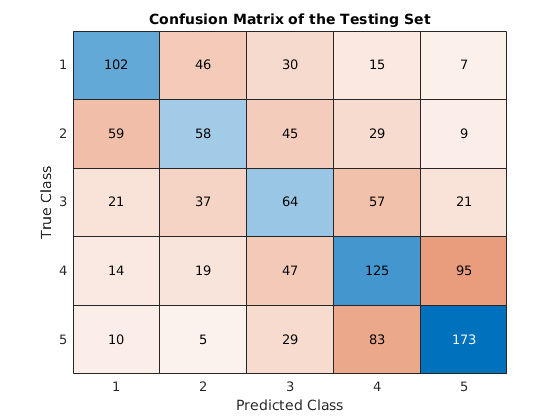

figure
confusionchart(CTest)
title("Confusion Matrix of the Testing Set")

% THis is reclassying the training points for a confusion matrix


% Predicting using the testing data set defined in the first section. 
PredictResultsTrain = classify(net,TrainXQ10);
% Checking the results of the test
TestNum = size(TrainXQ10,1);
correctNum = 0;
for i=1:TestNum
    %Computing the accuracy of the tests
    if PredictResultsTrain(i)==YTrainQ10(i)
        correctNum = correctNum + 1;
    end
end
TrainAccuracy = correctNum/TestNum

TrainAccuracy = 0.9828


% Creating a confusion matrix to show results 
CTrain = confusionmat(YTrainQ10,PredictResultsTrain)

CTrain =         1595           0           3           0           2
          25        1509          54          10           2
           5           0        1582          12           1
           3           1           2        2366          28
           4           0           1          12        2383


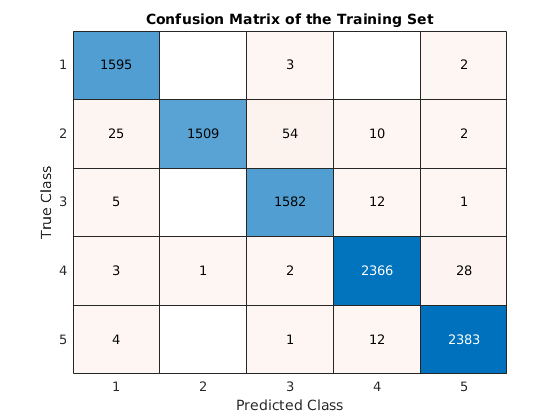

figure
confusionchart(CTrain)
title("Confusion Matrix of the Training Set")


% Predicting using the testing data set defined in the first section. 
PredictResultsValidate = classify(net,ValidationXQ10);
% Checking the results of the test
TestNum = size(ValidationXQ10,1);
correctNum = 0;
for i=1:TestNum
    %Computing the accuracy of the tests
    if PredictResultsValidate(i)==YValidationQ10(i)
        correctNum = correctNum + 1;
    end
end
ValidateAccuracy = correctNum/TestNum

ValidateAccuracy = 0.4450


% Creating a confusion matrix to show results 
CValidate = confusionmat(YValidationQ10,PredictResultsValidate)

CValidate =    120    30    28    10    12
    66    56    48    20    10
    29    24    78    48    21
    14    21    51   122    92
    14     8    23    97   158


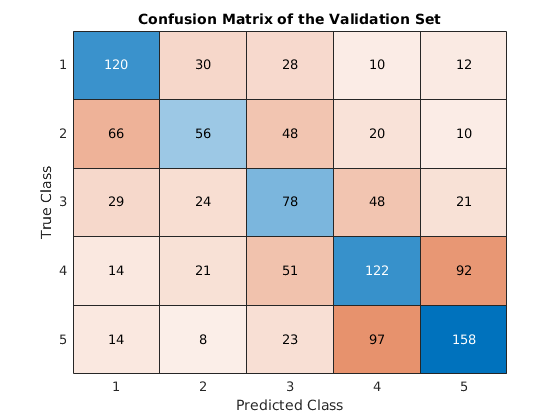

figure
confusionchart(CValidate)
title("Confusion Matrix of the Validation Set")

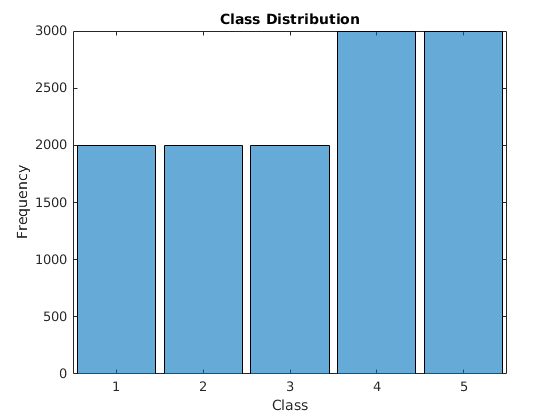


% This plots the categories to understand the data more. 
figure
histogram(AllData.Ratings);
xlabel("Class")
ylabel("Frequency")
title("Class Distribution")

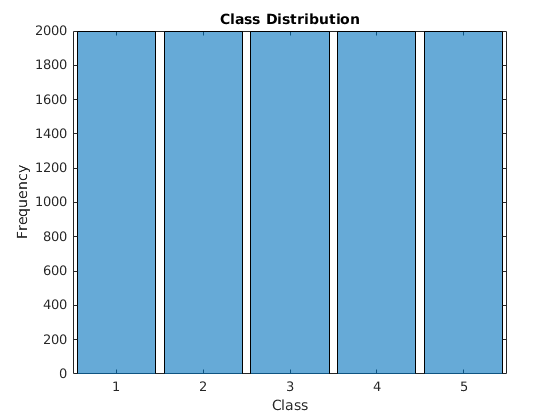

% Looking at the data I think to remove 1000 rows which belong to rating 5,
% And one thousand rows which belong to rating 4
% elements

% Know that 5's are the last 3000 elements of the array, so can just drop
% last 1000 rows from table from the All Data table. 4 is the elements
% This creates a tempory table of all the reviews with ratings 1,2 or 3. 
% balanced data is initally the same as Alldata, it is balanced using the
% above method
BalancedData = AllData;
BalancedData(11001:end,:) = [];
BalancedData(8001:9000,:) = [];

% This plots our dataset to see the distribution. 
figure
histogram(BalancedData.Ratings);
xlabel("Class")
ylabel("Frequency")
title("Class Distribution")

% This section is to retrain the model with the balanced data set. It uses
% the exact same method used earlier but with the balanced data set. 



% Convert teh labels to categories
Balanced.Ratings = categorical(BalancedData.Ratings);

% Variables are named to end in Q10 for readiability and to ensure that the
% Correct variables are used in their correct spots. 



% Splitting the data into the training and validating portions. 
cvp = cvpartition(BalancedData.Ratings,'Holdout',0.2);
TrainingDataQ10Balanced = BalancedData(training(cvp),:);
RemainingDataQ10Balanced = BalancedData(test(cvp),:);

cvp = cvpartition(RemainingDataQ10Balanced.Ratings,'Holdout',0.5);
ValidationDataQ10Balanced = RemainingDataQ10Balanced(training(cvp),:);
TestingDataQ10Balanced = RemainingDataQ10Balanced(test(cvp),:);

% Getting the text and the labels assocaited with them for the training,
% validation, and testing sets. 
TrainingTextDataQ10Balanced = TrainingDataQ10Balanced.Reviews;
ValidationTextDataQ10Balanced = ValidationDataQ10Balanced.Reviews;

YTrainQ10Balanced = TrainingDataQ10Balanced.Ratings;
YValidationQ10Balanced = ValidationDataQ10Balanced.Ratings;

TestingReviewsQ10Balanced = TestingDataQ10Balanced.Reviews;
TestingLablesQ10Balanced = TestingDataQ10Balanced.Ratings;



% Preprocessing the text data with my self defined function. Remember the
% bags are used to ensure my preprocess text function will run the way i
% want it too. It is not used so it does not matter the values associated
% with it
tokenziedDocsQ10Balanced = tokenizedDocument(TrainingTextDataQ10Balanced);
randombag = bagOfWords();
TrainingDocumentsQ10Balanced = preprocessText(TrainingTextDataQ10Balanced,randombag);

terms_2 = 15832

number_of_terms_removed_by2 = -15832

terms_3 = 15656

number_of_terms_removed_by3 = 176

terms_4 = 15273

number_of_terms_removed_by_4 = 383

terms_5 = 10981

number_of_terms_removed_by5 = 4292

terms_6 = 10677

number_of_terms_removed_by6 = 304

terms_7 = 10388

number_of_terms_removed_by7 = 289

terms_8 = 10295

number_of_terms_removed_by8 = 93

ValidationDocumentsQ10Balanced = preprocessText(ValidationTextDataQ10Balanced,randombag);

terms_2 = 5245

number_of_terms_removed_by2 = -5245

terms_3 = 5175

number_of_terms_removed_by3 = 70

terms_4 = 4890

number_of_terms_removed_by_4 = 285

terms_5 = 3609

number_of_terms_removed_by5 = 1281

terms_6 = 3558

number_of_terms_removed_by6 = 51

terms_7 = 3443

number_of_terms_removed_by7 = 115

terms_8 = 3434

number_of_terms_removed_by8 = 9


%pre-process the test set and remember to use the random bag
TestingDocumentsQ10Balanced = preprocessText(TestingReviewsQ10Balanced,randombag);

terms_2 = 5157

number_of_terms_removed_by2 = -5157

terms_3 = 5092

number_of_terms_removed_by3 = 65

terms_4 = 4805

number_of_terms_removed_by_4 = 287

terms_5 = 3586

number_of_terms_removed_by5 = 1219

terms_6 = 3529

number_of_terms_removed_by6 = 57

terms_7 = 3412

number_of_terms_removed_by7 = 117

terms_8 = 3398

number_of_terms_removed_by8 = 14

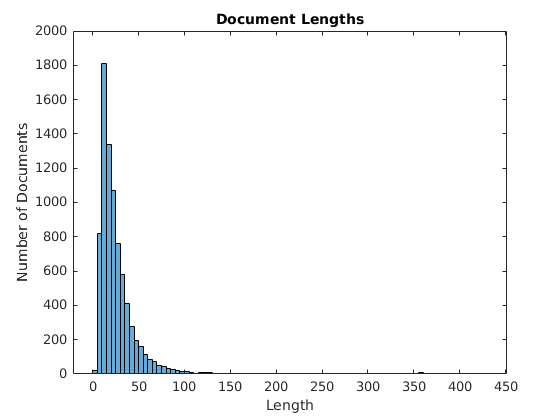





% Creating a word Encoding to ensure that we can retrain the model.
% And convert the documents to sequances. 
enc = wordEncoding(TrainingDocumentsQ10Balanced);

% Pad and truncate the documents
documentLengths = doclength(TrainingDocumentsQ10Balanced);
figure
histogram(documentLengths)
title("Document Lengths")
xlabel("Length")
ylabel("Number of Documents")


% Convert the documents to sequences and save them to the training and
% testing values. 
sequenceLength = 100;
TrainXQ10Balanced = doc2sequence(enc,TrainingDocumentsQ10Balanced,'Length',sequenceLength);
ValidationXQ10Balanced = doc2sequence(enc,ValidationDocumentsQ10Balanced,'Length',sequenceLength); 
TestXQ10Balanced = doc2sequence(enc,TestingDocumentsQ10Balanced,'Length',sequenceLength);

% This recreates the LSTM model from task 9, but it used the encdoing
% created in task 10 instead. This means the numWords is changed to match the new encoding.  
inputSize = 1;
embeddingDimension = 50;
numHiddenUnits = 80;
numWords = enc.NumWords;
numClasses = numel(categories(YTrainQ10));
layers = [ ...
    sequenceInputLayer(inputSize)
    wordEmbeddingLayer(embeddingDimension,numWords)
    lstmLayer(numHiddenUnits,'OutputMode','last')
    fullyConnectedLayer(numClasses)
    fullyConnectedLayer(numClasses)
    softmaxLayer
    classificationLayer]

layers =   7x1 Layer array with layers:

     1   ''   Sequence Input          Sequence input with 1 dimensions
     2   ''   Word Embedding Layer    Word embedding layer with 50 dimensions and 10295 unique words
     3   ''   LSTM                    LSTM with 80 hidden units
     4   ''   Fully Connected         5 fully connected layer
     5   ''   Fully Connected         5 fully connected layer
     6   ''   Softmax                 softmax
     7   ''   Classification Output   crossentropyex


% Specify Training Options
%https://www.mathworks.com/help/deeplearning/ref/trainingoptions.html
options = trainingOptions('adam', ...
    'MiniBatchSize',16, ...
    'GradientThreshold',2, ...
    'LearnRateDropFactor',0.2, ...
    'LearnRateDropPeriod',5, ...
    'ValidationData',{ValidationXQ10Balanced,YValidationQ10Balanced}, ...
    'Plots','training-progress',...
    'Verbose',false)

options =   TrainingOptionsADAM with properties:

           GradientDecayFactor: 0.9000
    SquaredGradientDecayFactor: 0.9990
                       Epsilon: 1.0000e-08
              InitialLearnRate: 1.0000e-03
             LearnRateSchedule: 'none'
           LearnRateDropFactor: 0.2000
           LearnRateDropPeriod: 5
              L2Regularization: 1.0000e-04
       GradientThresholdMethod: 'l2norm'
             GradientThreshold: 2
                     MaxEpochs: 30
                 MiniBatchSize: 16
                       Verbose: 0
              VerboseFrequency: 50
                ValidationData: {{1000×1 cell}  [1000×1 categorical]}
           ValidationFrequency: 50
            ValidationPatience: Inf
                       Shuffle: 'once'
                CheckpointPath: ''
          ExecutionEnvironment: 'auto'
                    WorkerLoad: []
                     OutputFcn: []
        

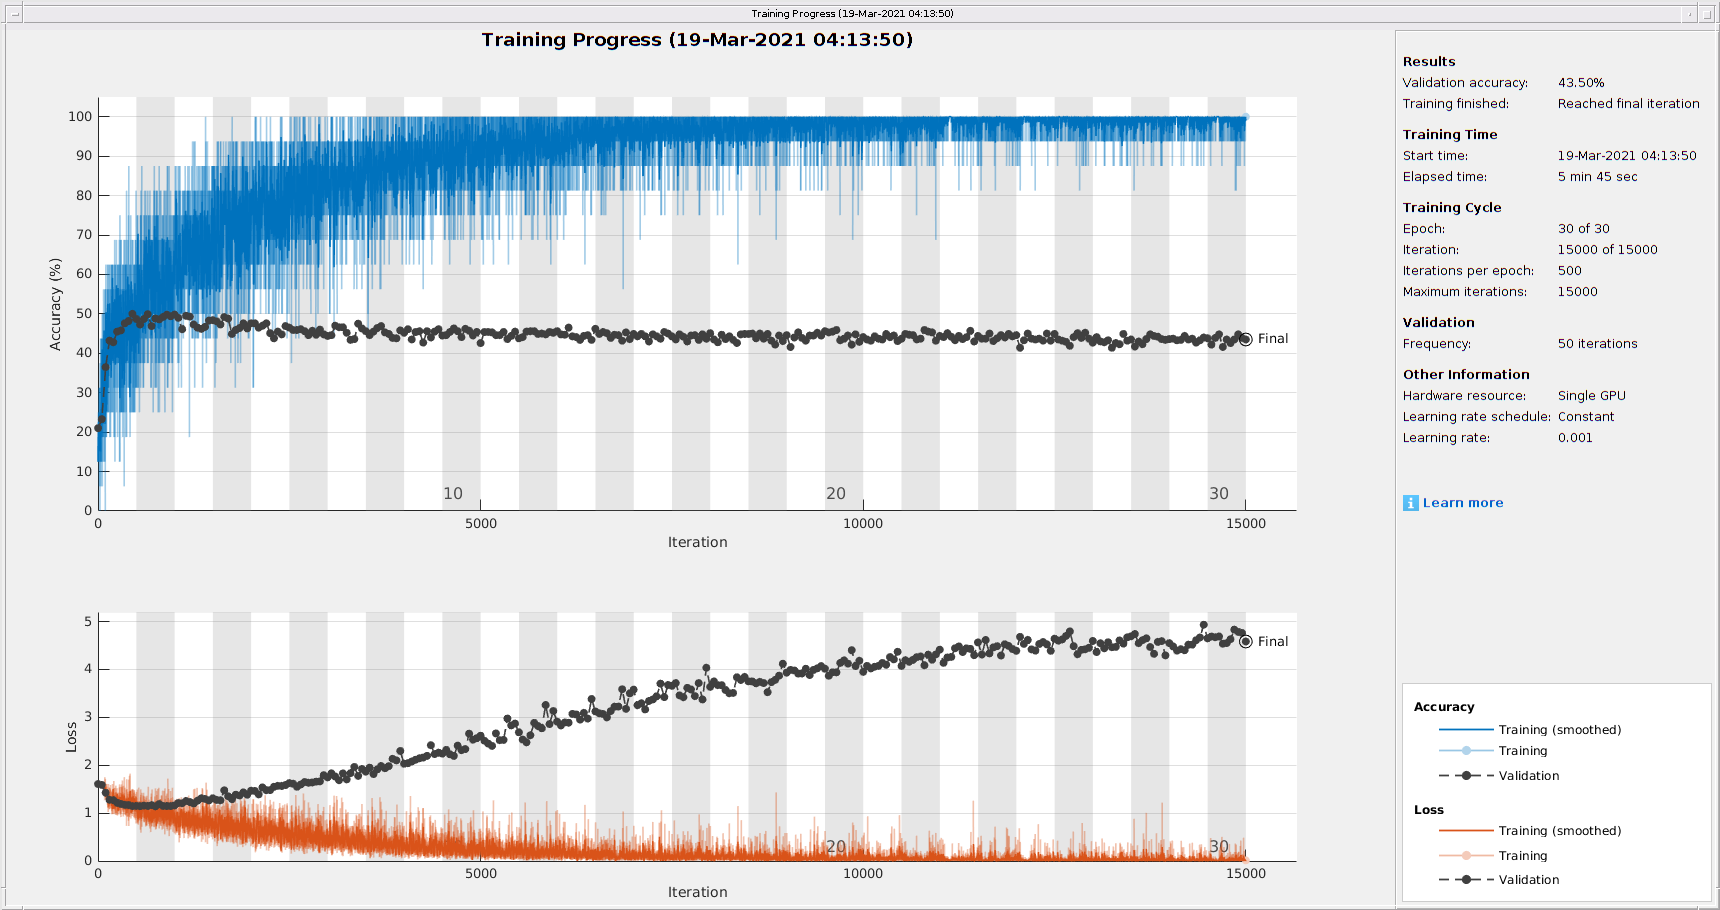



% This re trains the network made in question 9 using the data above. 
net2 = trainNetwork(TrainXQ10Balanced,YTrainQ10Balanced,layers,options);


% Predicting using the testing data set defined in the first section. 
PredictResultsTest = classify(net2,TestXQ10Balanced);
% Checking the results of the test
TestNum = size(TestXQ10Balanced,1);
correctNum = 0;
for i=1:TestNum
    % Displaying some results. Will not do it for all
    if i<=20
        sprintf('Review: %s\nPredicted Result: %s\nLabel Rating: %s', TestingReviewsQ10Balanced(i),PredictResultsTest(i),TestingLablesQ10Balanced(i))
    end
    %Computing the accuracy of the tests
    if PredictResultsTest(i)==TestingLablesQ10Balanced(i)
        correctNum = correctNum + 1;
    end
end

ans =     'Review: I have generally had very good experience ordering jewelry from Amazon sellers, so I ordered two of these necklace pendants, one for myself and one for my mother. Both arrived with very badly tarnished chains (about half the chain rust colored on both). In addition, the actual pendants were scratched and "used looking".
     
     Predicted Result: 1
     Label Rating: 1'


ans =     'Review: I was very disappointed in the ring. The color is grey not sterling bright. I was looking for the somerset mesh ring but it was not available in size 9 so ordered this one which looked the same but was NOT i plan to return the ring.
     
     Predicted Result: 1
     Label Rating: 1'


ans =     'Review: I ordered 3 items. This necklace came to me with a nasty kink and a ring that had a dent in it.I had to send it back paying for the shipping handling......so I paid for the initial shipping and handling as well as the shipping and handling to send it backThis company is ripping off consumers!!!!!!!!!!!!!!!!!!
     
     Predicted Result: 1
     Label Rating: 1'


ans =     'Review: At first glance this ring looks like no other. Ever since then, however, it has been nothing but a horrible mess. The tarnish free has tarnished! All of the stones lose their shine! Everything gets caught in the inside of the ring because it is practically hollow. If it even skims something it scratches. All in all nothing but a piece of junk!
     
     Predicted Result: 3
     Label Rating: 1'


ans =     'Review: One look was enough ... sent back immediately. Packaging was nice though but quality was definitely sub par especially how light weight they were ... settings were cheap too.
     
     Predicted Result: 2
     Label Rating: 1'


ans =     'Review: First, the color of the stones is lighter than is pictured. I realize it is hard to capture color in a picture, but the ring I received has stones that are light purple to almost a pink color. For the price of the ring I can deal with that though, I mean, what can you expect for $29? The worst part is that it's just hard to wear because it's not comfortable. It would have been better with five stones instead of seven because the two outer stones rub against your other fingers and it gets annoying fast. I'll be returning this ring and will try something else.
     
     Predicted Result: 1
     Label Rating: 1'


ans =     'Review: Come on, people! If these products really worked, everyone would wear them! The manufacturers want you to think they work, so they can sell them and make $$$. I have tried the phiten, and the balance bracelet, and magnetic therapy. I have noticed no change in my myriad aches, pains, and stiffnesses. I have worn a phiten necklace for over a month, just to give it a chance. If anything, I feel worse with it on, so I am giving up. Save your money!
     
     Predicted Result: 1
     Label Rating: 1'


ans =     'Review: I don't know who the hell thinks this works, but it doesn't. Nice necklace though. I haven't stopped wearing it just because I don't have any other necklace to wear.
     
     Predicted Result: 1
     Label Rating: 1'


ans =     'Review: I was really disappointed with my pair of Eide Black Tahitian cultured pearl earrings. Instead of the beautiful pair of greenish black pear shaped unblemished pearls shown above, I got a pair of greenish/pinkish totally irregular black "apple" shaped blemished pearls.I felt misled by the description and image of the product.For comparison, I will be sharing an image of the pair I got.I do not recommend this product.
     
     Predicted Result: 2
     Label Rating: 1'


ans =     'Review: You have got to be one of the most difficult websites to navigate, and the most difficult to find how to contact a person with which to discuss a problem ordering!
     
     Predicted Result: 1
     Label Rating: 1'


ans =     'Review: This 14K Yellow Gold 7 Inch x 3.0 mm Figaro chain bracelet felt like tin and had an unattractive bright yellow shine. It had the type of shine were I felt if the bracelet were larger I could clearly see my face in it. The edges of the bracelet were rough on the skin. So it went back in the box and was returned. I was a very disappointed customer.
     
     Predicted Result: 1
     Label Rating: 1'


ans =     'Review: I wish I had given more credibility to the negative reviews. Frankly, I don't understand how there ecould be so many positive reviews. It's an ok chain - if you want to wear it by itself. But it's not good for pendants, as advertised. It remains perfectly stiff and oval shaped when worn - even a large pendant doesn't pull the chain down as a pendant normally does. I'm returning it.
     
     Predicted Result: 1
     Label Rating: 1'


ans =     'Review: Yes, they are small, but what I got and what's in the picture are not even close! My earrings are all orange stones with none of the lovely shading that enticed me to order them. Talk about being disappointed, that's an understatement. Too bad, so sad, I've been had.
     
     Predicted Result: 2
     Label Rating: 1'


ans =     'Review: Beware - this product looks nothing like the picture. There is no detail - just a tiny flat piece of gold and definitely not worth the price, and the bale is not even soldered. I sent it back.
     
     Predicted Result: 1
     Label Rating: 1'


ans =     'Review: I received my belly ring today and I was very surprised with the shipping since it is holiday season, but the product is not as pictured. The balls are a dirty white pearl color not the glittery white as pictured. It it also super long. I don't know if it's made for people with piercings farther back or what but it sticks out way to much for my comfort and I took it off after an hour thinking I may rip it out on accident.
     
     Predicted Result: 2
     Label Rating: 1'


ans =     'Review: This device is way to hard to use...can't calibrate the dang thing. I'm sure it will never work properly. Not at all impressed.
     
     Predicted Result: 3
     Label Rating: 1'


ans =     'Review: I was disappointed that the actual vs. online photo was not attractive. Shipping was very timely and the nice packaging prevented any transit damage. Vendor has a very large selection. The shipping fee assessed at the point of purchase was equal to a fourth of the price of the product at my price point and there is no free shipping on returns. The customer service rep was defensive when I shared my disappointment. A refund was promptly received. I am not interested in reordering.
     
     Predicted Result: 3
     Label Rating: 1'


ans =     'Review: When I recived item ordered, it was cute, it looked like what I wanted, but it was broken. The fairy dancer that was suppose to be standing was broken off. It was a Christmas gift, I was dissappointed.
     
     Predicted Result: 2
     Label Rating: 1'


ans =     'Review: Ok so I never ever write a review but my daughter just received this as a present. It is a beautiful and well made jewelry box but the sticker on the package as well as the box said that it contains lead. I am appalled that a product that is obviously made for children is still being sold even if it is labeled as containing lead! I will definitely be returning this one!
     
     Predicted Result: 2
     Label Rating: 1'


ans =     'Review: OMG ... they are extremely tiny - Do not go by the picture . It is a 5-6x magnified version of whats in the box.Pretty for a 3-4 year old!If you are looking forward to seeing the 4 diamonds and the sapphire on your own "adult" ears even in a mirror - forget it - Not VISIBLE!
     
     Predicted Result: 2
     Label Rating: 1'


TestAccuracy = correctNum/TestNum

TestAccuracy = 0.4570


% Creating a confusion matrix to show results 
CTest = confusionmat(TestingLablesQ10Balanced,PredictResultsTest)

CTest =     97    60    30     4     9
    46    83    45    15    11
    24    46    87    25    18
    12    28    40    71    49
     9    11    14    47   119


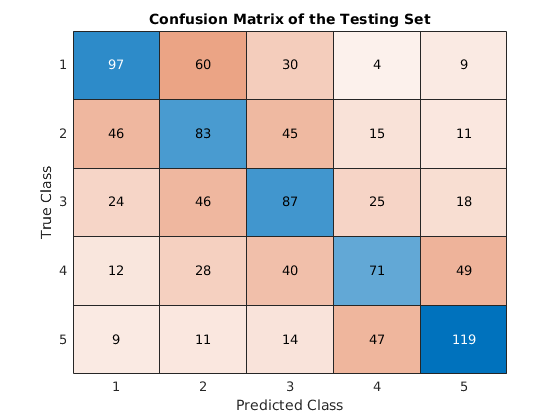

figure
confusionchart(CTest)
title("Confusion Matrix of the Testing Set")

% THis is reclassying the training points for a confusion matrix


% Predicting using the testing data set defined in the first section. 
PredictResultsTrain = classify(net2,TrainXQ10Balanced);
% Checking the results of the test
TestNum = size(TrainXQ10Balanced,1);
correctNum = 0;
for i=1:TestNum
    %Computing the accuracy of the tests
    if PredictResultsTrain(i)==YTrainQ10Balanced(i)
        correctNum = correctNum + 1;
    end
end
TrainAccuracy = correctNum/TestNum

TrainAccuracy = 0.9926


% Creating a confusion matrix to show results 
CTrain = confusionmat(YTrainQ10Balanced,PredictResultsTrain)

CTrain =         1596           2           0           0           2
           7        1592           1           0           0
           5          11        1578           5           1
           0           6           8        1577           9
           0           0           0           2        1598


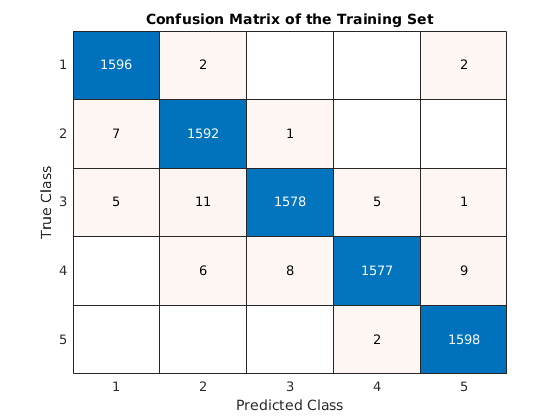

figure
confusionchart(CTrain)
title("Confusion Matrix of the Training Set")


% Predicting using the testing data set defined in the first section. 
PredictResultsValidate = classify(net2,ValidationXQ10Balanced);
% Checking the results of the test
TestNum = size(ValidationXQ10Balanced,1);
correctNum = 0;
for i=1:TestNum
    %Computing the accuracy of the tests
    if PredictResultsValidate(i)==YValidationQ10Balanced(i)
        correctNum = correctNum + 1;
    end
end
ValidateAccuracy = correctNum/TestNum

ValidateAccuracy = 0.4350


% Creating a confusion matrix to show results 
CValidate = confusionmat(YValidationQ10Balanced,PredictResultsValidate)

CValidate =    106    64    25     3     2
    44    79    50    19     8
    20    55    71    39    15
    16    20    42    70    52
     7    13    20    51   109


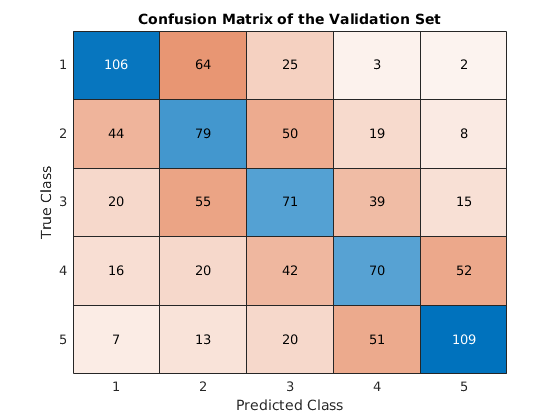

figure
confusionchart(CValidate)
title("Confusion Matrix of the Validation Set")